clear; clc; close all;

Tc = 0.01;

### Verifica LTI

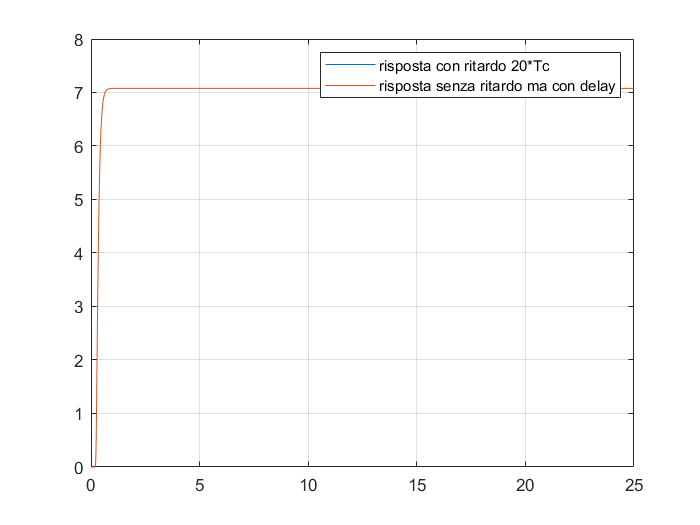

verificaLTI = sim('verificaModelloLTI');
figure(1);
plot(verificaLTI.t,verificaLTI.yTI);
grid;
legend("risposta con ritardo 20*Tc","risposta senza ritardo ma con delay");

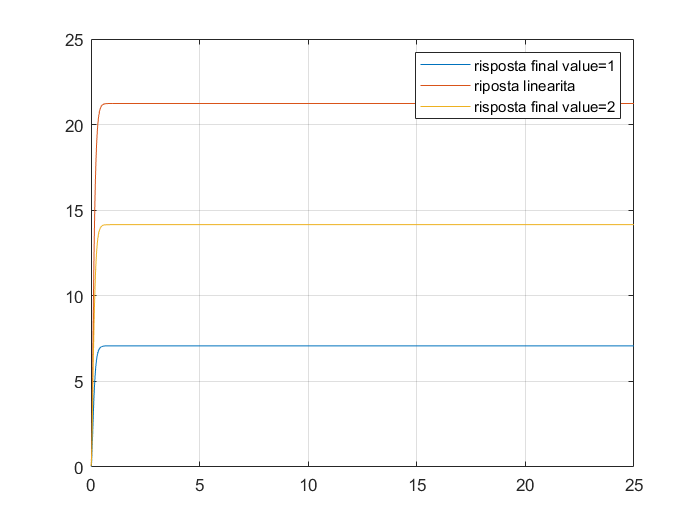

figure(2);
plot(verificaLTI.t,verificaLTI.yL);
legend('risposta final value=1','riposta linearita','risposta final value=2');
grid;

### Generazione misure del processo black-box

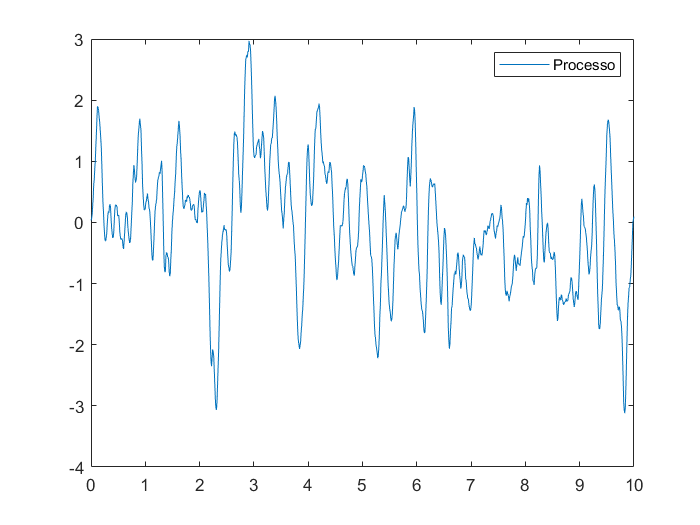

simulazione = sim('genera_misure');
t = simulazione.t;
u = simulazione.u;
z = simulazione.z;
figure(3);
plot(t,z);
legend('Processo');

### Costruzione e analisi del modello

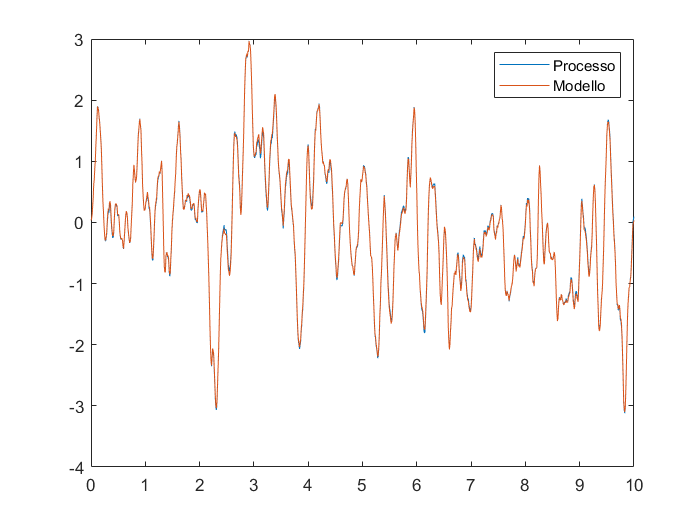

n = 4; m = 4;
Z = z(max(n,m)+1:end);
fi = zeros(1,n+m+1);
FI = [];

T = length(t);

for k=max(n,m):T-1
    for j=1:n
        fi(j) = -z(k-j+1);
    end
    for j=1:m+1
        fi(j+n) = u(k-j+2);
    end
    FI=[FI;fi];
end

teta = FI\Z;
Gz = tf(teta(n+1:end)',[1;teta(1:n)]',Tc,'Variable','z^-1');


figure(4);
plot(t,z);
hold on
y = lsim(Gz,u,t);
plot(t,y);
legend('Processo','Modello');

### Implementazione modello ARMA, Forma Canonica I e Forma Canonica II

[b a] = tfdata(Gz,'v');
b0 = b(1); b1 = b(2); b2 = b(3); b3 = b(4); b4 = b(5);
a0 = a(1); a1 = a(2); a2 = a(3); a3 = a(4); a4 = a(5);

validazione_modello = sim('validazione_modello');
time = validazione_modello.time;

#### Analisi risposta all'ingresso random 

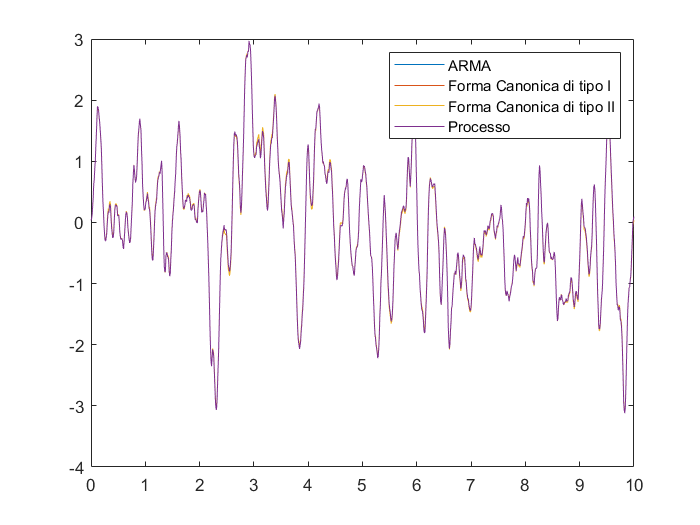

figure(5);
title('[t u] output');
tu_output = validazione_modello.tu_output;
plot(time, tu_output);
legend('ARMA','Forma Canonica di tipo I','Forma Canonica di tipo II','Processo');

#### Analisi risposta al gradino

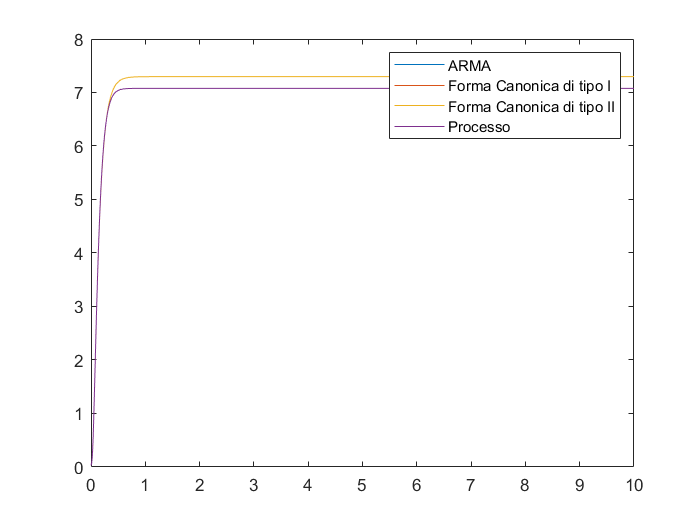

figure(6);
title('step output');
step_output = validazione_modello.step_output;
plot(time, step_output);
legend('ARMA','Forma Canonica di tipo I','Forma Canonica di tipo II','Processo');


stepP = validazione_modello.step_processo;
stepA = validazione_modello.step_ARMA;
err_ass_step_array = abs(stepA-stepP);
err_ass_step = mean( err_ass_step_array );

#### Analisi risposta al treno di impulsi

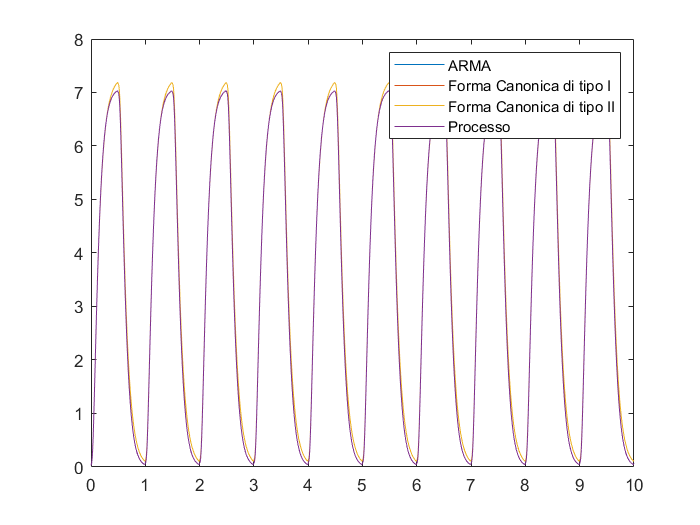

figure(7);
title('pulse output');
pulse_output = validazione_modello.pulse_output;
plot(time, pulse_output);
legend('ARMA','Forma Canonica di tipo I','Forma Canonica di tipo II','Processo');


pulseP = validazione_modello.pulse_processo;
pulseA = validazione_modello.pulse_ARMA;
err_ass_pulse_array = abs(pulseA-pulseP);
err_ass_pulse = mean( err_ass_pulse_array );

#### Risposta alla sinusoide

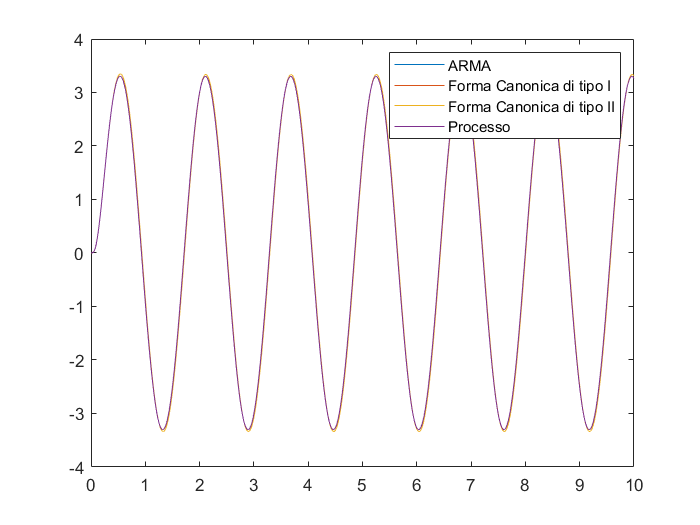

figure(8);
title('sine wave output');
sine_wave = validazione_modello.sine_wave_output;
plot(time, sine_wave);
legend('ARMA','Forma Canonica di tipo I','Forma Canonica di tipo II','Processo');


sine_waveP = validazione_modello.sine_wave_processo;
sine_waveA = validazione_modello.sine_wave_ARMA;
err_ass_sine_wave_array = abs( sine_waveA-sine_waveP );
err_ass_sine_wave = mean( err_ass_sine_wave_array );

